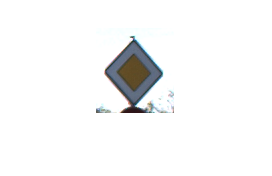

clc
close all


image = imread("00012_00000_00029.png");
imshow(image)

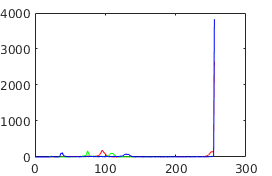


%Split into RGB Channels
Red = image(:,:,1);
Green = image(:,:,2);
Blue = image(:,:,3);
%Get histValues for each channel
[yRed, x] = imhist(Red);
[yGreen, x] = imhist(Green);
[yBlue, x] = imhist(Blue);
%Plot them together in one plot
plot(x, yRed, 'Red', x, yGreen, 'Green', x, yBlue, 'Blue');

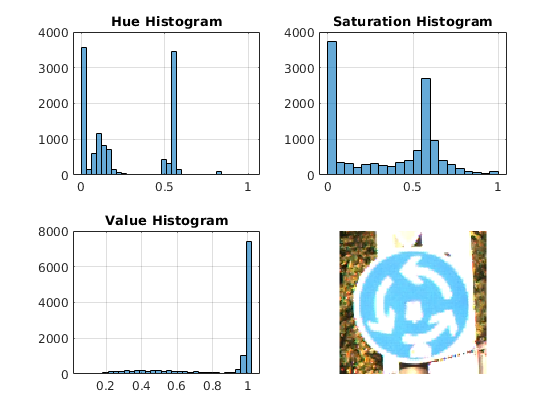


rgbImage = imread('00040_00009_00029.png');
hsvImage = rgb2hsv(rgbImage);
hImage = hsvImage(:, :, 1);
sImage = hsvImage(:, :, 2);
vImage = hsvImage(:, :, 3);
figure;
subplot(2,2,1);
hHist = histogram(hImage);
grid on;
title('Hue Histogram');
subplot(2,2,2);
sHist = histogram(sImage);
grid on;
title('Saturation Histogram');
subplot(2,2,3);
vHist = histogram(vImage);
grid on;
title('Value Histogram');
subplot(2,2,4);
imshow(rgbImage);